# Pain only stimulus intensity maps

# Linear effects of stimlus intensity (low < med < high)

Pain only :: load dataset

clear all;
close all;

contrast_of_interest = 'P_simple_STIM_cue_high_gt_low'

contrast_of_interest = 'P_simple_STIM_cue_high_gt_low'

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue_rampplateau/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low','V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_cue_high_gt_low','V_PC_CUE_cue_high_gt_low','C_PV_CUE_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_cue_high_gt_low','V_simple_CUE_STIM_cue_high_gt_low','C_simple_CUE_cue_high_gt_low',...% cue epoch dummy
    'G_simple_CUE_cue_high_gt_low',...
    'P_VC_STIM', 'V_PC_STIM', 'C_PV_STIM'
};
index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 28753056 bytes
Loading image number:    72
Elapsed time is 15.508870 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6899522  Bit rate: 22.72 bits


`Pain only :: check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:31:04 - 16/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


asdf

Pain only :: Plot diagnostics, before l2norm

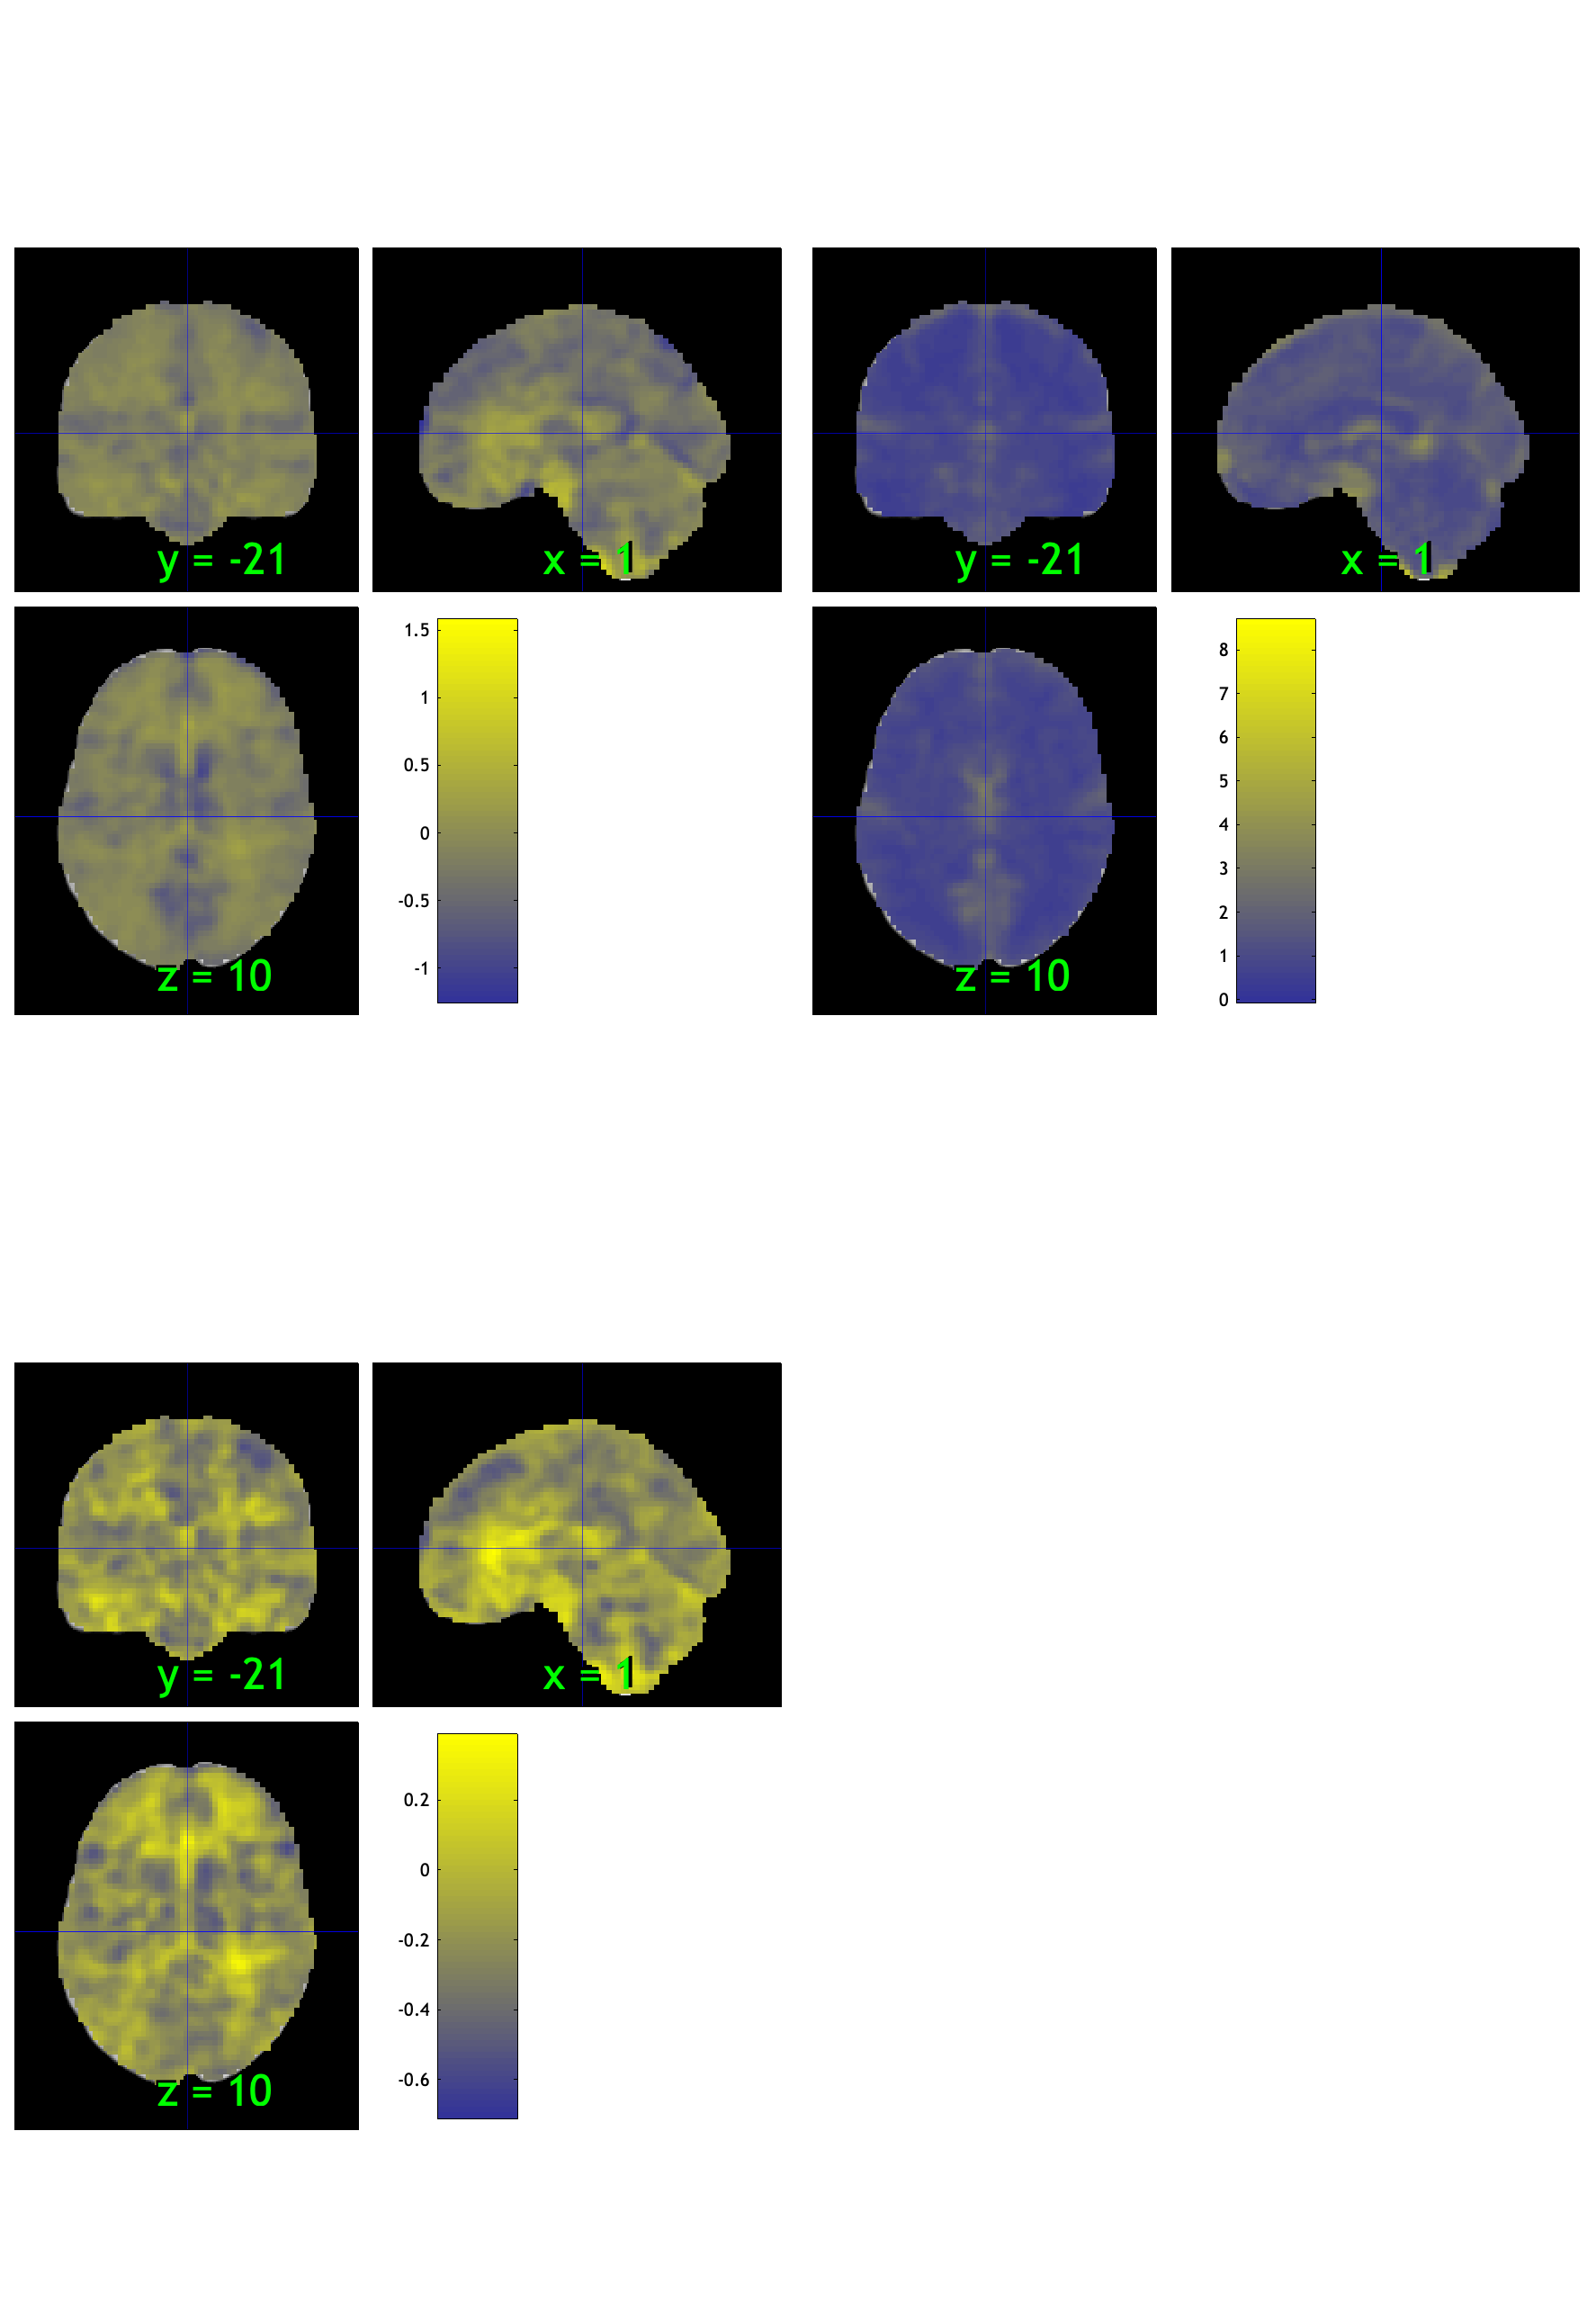

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 29.17%
Expected 3.60 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 29 44 
Uncorrected: 7 images		Cases 7 26 29 37 44 65 70 

Retained 7 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 56.94%
Expected 3.60 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 1 images		Cases 58 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                               

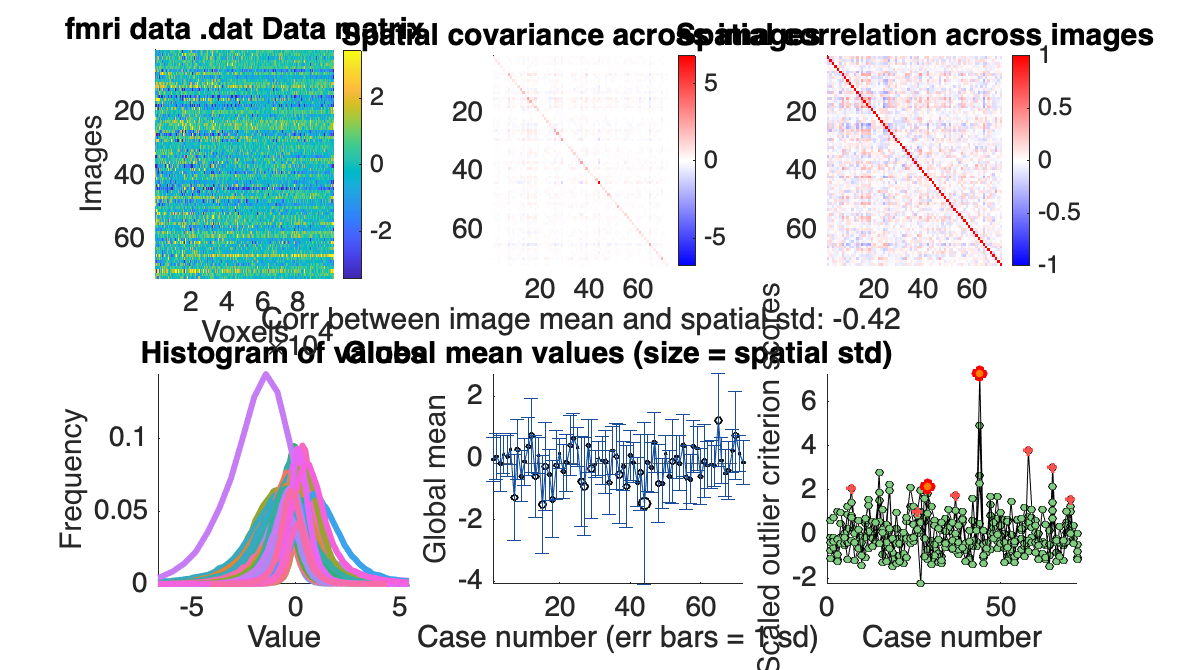

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              10:31:45 - 16/01/2024
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

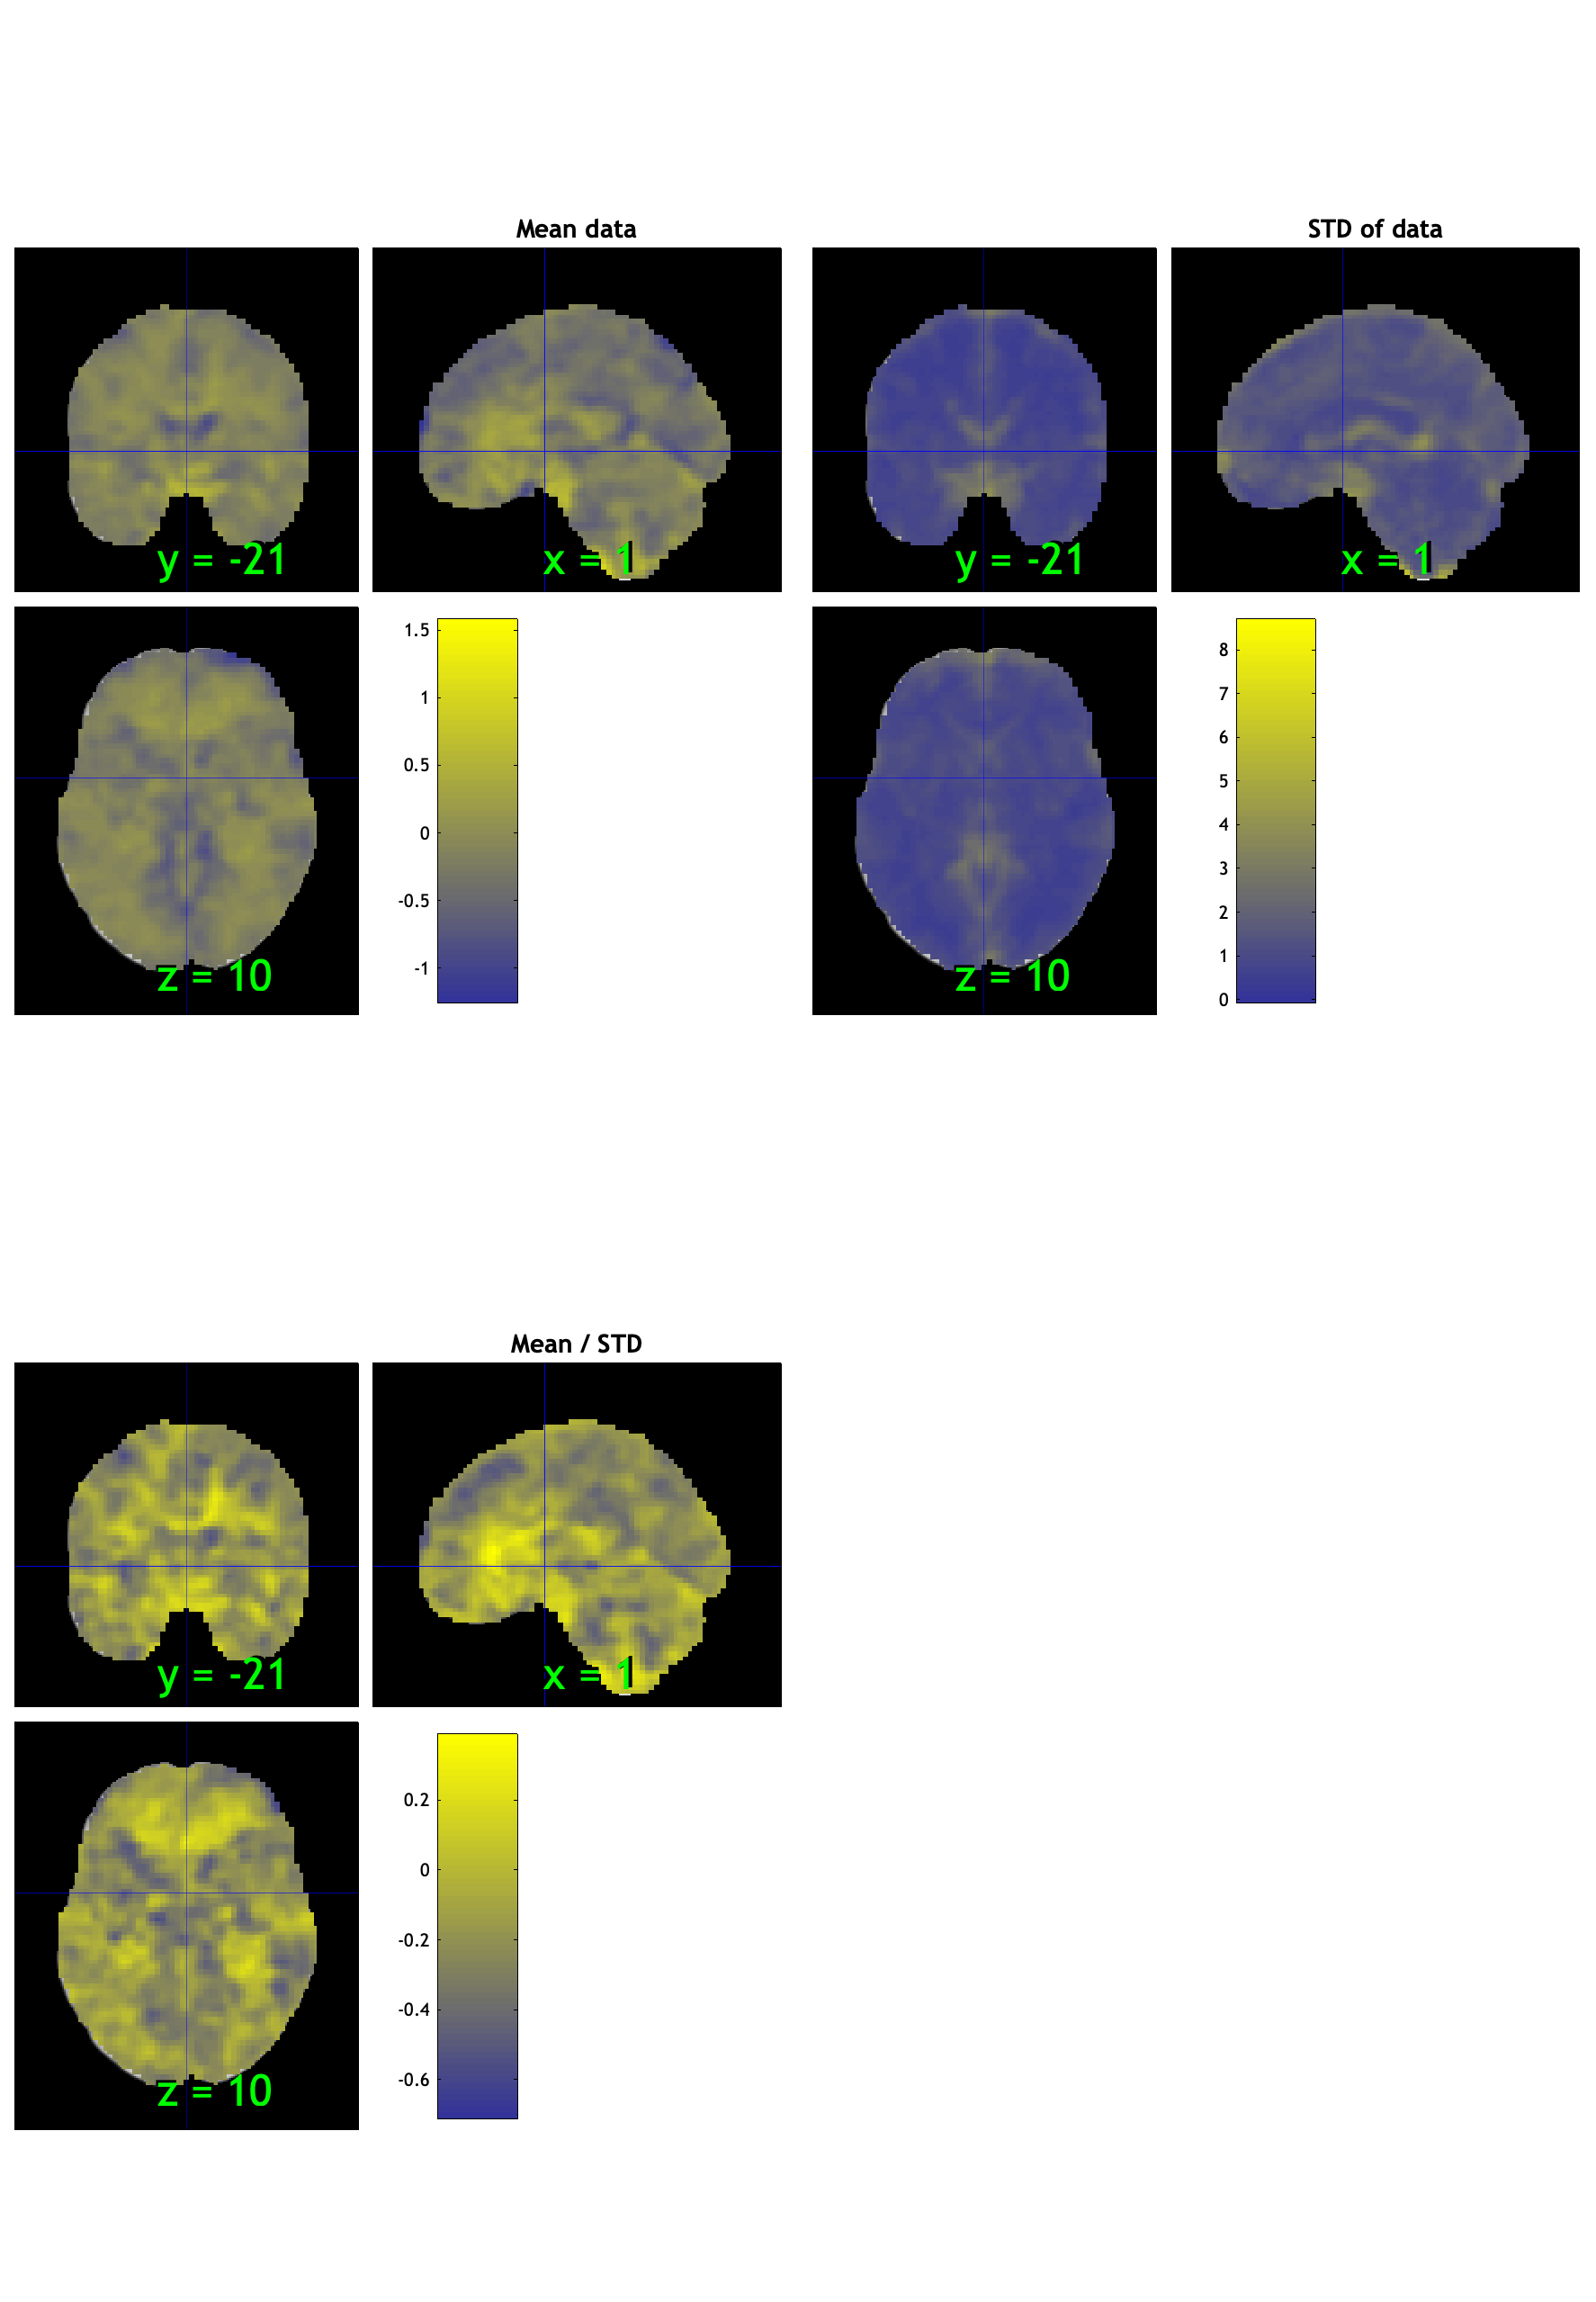

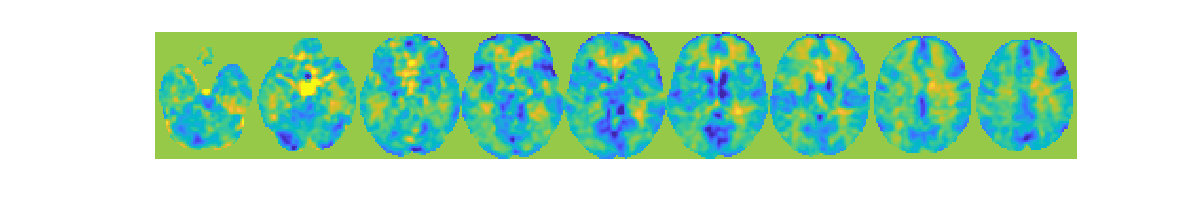

drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

Remove outlier

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 72


%for s = 1:length(wh_outlier_corr)
%disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 2 participants, size is now 70


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0074"    "participants that are outliers:... sub-0093"



disp(n);

`imgs2 = con.rescale(``'l2norm_images');`

# `regression`

### `Load behavioral cue effects. prepare covariates and identify intersection subjects with fMRI data`

beh_cueeffect = readtable('/Users/h/Documents/projects_local/cue_expectancy/data/hlm/cue_stim_effects_scaling.csv')

beh_cueeffect = 342×22 table
        sub             task         cue_raw_outcome    cue_raw_outcome_sd    cue_z_outcome    cue_z_outcome_sd    cue_raw_expect    cue_raw_expect_sd    cue_z_expect    cue_z_expect_sd    stim_raw_outcome    stim_raw_outcome_sd    stim_z_outcome    stim_z_outcome_sd    stim_raw_expect    stim_raw_expect_sd    stim_z_expect    stim_z_expect_sd    cuestim_raw_outcome    cuestim_raw_outcome_reg    cuestim_z_outcome    cuestim_z_outcome_reg
    ____________    _____________    _______________    __________________    _

pain_task = find(strcmp(beh_cueeffect.task, 'pain'));

pain_cueeffect = beh_cueeffect(pain_task, :);

% extract subject ids from contrast fMRI data object and intersect with
% behavioral data
nRows = size(con_data_obj.image_names, 1);
sub_ids = cell(nRows, 1);

for i = 1:nRows
    sub_ids{i} = con_data_obj.image_names(i, 1:8);
end

sub_ids_table = table(sub_ids, 'VariableNames', {'sub'});
common_subs = intersect(sub_ids_table.sub, pain_cueeffect.sub)

common_subs = 71×1 cell array
    {'sub-0014'}
    {'sub-0026'}
    {'sub-0028'}
    {'sub-0029'}
    {'sub-0030'}
    {'sub-0031'}
    {'sub-0033'}
    {'sub-0035'}
    {'sub-0039'}
    {'sub-0040'}
    {'sub-0041'}
    {'sub-0043'}
    {'sub-0044'}
    {'sub-0047'}
    {'sub-0050'}
    {'sub-0051'}
    {'sub-0053'}
    {'sub-0055'}
    {'sub-0058'}
    {'sub-0060'}
    {'sub-0061'}
    {'sub-0062'}
    {'sub-0064'}
    {'sub-0066'}
    {'sub-0068'}
    {'sub-0069'}
    {'sub-0070'}
    {'sub-0073'}
    {'sub-0074'}
    {'sub-0076'}


% Ensure beh_cueeffect.sub is a cell array for comparison
if ~iscell(pain_cueeffect.sub)
    pain_cueeffect.sub = cellstr(pain_cueeffect.sub);
end

rows_to_keep = ismember(pain_cueeffect.sub, common_subs);
filtered_pain_cueeffect = pain_cueeffect(rows_to_keep, :);

% regenerate contrast filenames based on intersecting subject ids
% Initialize an empty cell array for the file paths
filteredcon_files = cell(length(common_subs), 1);

% Loop through each subject ID and construct the file path
for i = 1:length(common_subs)
    filteredcon_files{i} = fullfile(mount_dir, common_subs{i}, [common_subs{i}, '_con_0020.nii']);
end


# covariates "Cue effects (Raw outcome)"

Adding Raw covariates to fmri data obj

filtered_con_obj = fmri_data(filteredcon_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 28353708 bytes
Loading image number:    71
Elapsed time is 16.077480 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6767782  Bit rate: 22.69 bits


filtered_con_obj.X = filtered_pain_cueeffect.cue_raw_outcome;

Error using  . 
Unrecognized table variable name 'raw_outcome_cue'.

plot(filtered_con_obj)
cue_raw_outcome = regress(filtered_con_obj, .05, 'fdr')
cue_raw_outcome.t = threshold(cue_raw_outcome.t, .05, 'fdr');
montage(cue_raw_outcome.t)

# covariates "Cue effects (Zscore)"

cue_z_outcome_obj = fmri_data(filteredcon_files);
cue_z_outcome_obj.X = filtered_pain_cueeffect.cue_z_outcome;
plot(cue_z_outcome_obj)
cue_z_outcome_obj = regress(cue_z_outcome_obj, .05, 'fdr')
cue_z_outcome_obj.t = threshold(cue_z_outcome_obj.t, .05, 'fdr');
montage(cue_z_outcome_obj.t)

# covariates cue vs. stim effects (raw)

cuestim_outcome_raw_obj = fmri_data(filteredcon_files);
cuestim_outcome_raw_obj.X = filtered_pain_cueeffect.cuestim_raw_outcome;
plot(cuestim_outcome_raw_obj)
cuestim_outcome_raw_obj = regress(cuestim_outcome_raw_obj, .05, 'fdr')
cuestim_outcome_raw_obj.t = threshold(cuestim_outcome_raw_obj.t, .05, 'fdr');
montage(cuestim_outcome_raw_obj.t)

# covariate "cue stim effect ratio (Z score)

cuestim_z_outcome_obj = fmri_data(filteredcon_files);
cuestim_z_outcome_obj.X = filtered_pain_cueeffect.cuestim_z_outcome;
plot(cuestim_z_outcome_obj)
cuestim_z_outcome_obj = regress(cuestim_z_outcome_obj, .05, 'fdr')
cuestim_z_outcome_obj.t = threshold(cuestim_z_outcome_obj.t, .05, 'fdr');
montage(cuestim_z_outcome_obj.t)


# covariate: cue stim effect ratio (raw score) regularized


cuestim_raw_outcome_reg_obj = fmri_data(filteredcon_files);
cuestim_raw_outcome_reg_obj.X = filtered_pain_cueeffect.cuestim_raw_outcome_reg;
plot(cuestim_raw_outcome_reg_obj)
cuestim_raw_outcome_reg_obj = regress(cuestim_raw_outcome_reg_obj, .05, 'fdr')
cuestim_raw_outcome_reg_obj.t = threshold(cuestim_raw_outcome_reg_obj.t, .05, 'fdr');
montage(cuestim_raw_outcome_reg_obj.t)

# covariate: cue stim effect ratio (Z score) regularized


cuestim_z_outcome_reg_obj = fmri_data(filteredcon_files);
cuestim_z_outcome_reg_obj.X = filtered_pain_cueeffect.cuestim_z_outcome_reg;
plot(cuestim_z_outcome_reg_obj)
cuestim_z_outcome_reg_obj = regress(cuestim_z_outcome_reg_obj, .05, 'fdr')
cuestim_z_outcome_reg_obj.t = threshold(cuestim_z_outcome_reg_obj.t, .05, 'fdr');
montage(cuestim_z_outcome_reg_obj.t)

# compile Tmaps and apply NPS

cue_raw_outcome = apply_nps(cue_raw_outcome.t);
cue_z_outcome = apply_nps(cue_z_outcome_obj.t);
cuestim_outcome_raw = apply_nps(cuestim_outcome_raw_obj.t);
cuestim_z_outcome = apply_nps(cuestim_z_outcome_obj.t);
cuestim_raw_outcome_reg = apply_nps(cuestim_raw_outcome_reg_obj.t)
cuestim_z_outcome_reg = apply_nps(cuestim_z_outcome_reg_obj.t);

cue_effects = table(cue_raw_outcome{1}(2), ...
    cue_z_outcome{1}(2), ...
    cuestim_outcome_raw{1}(2), ...
    cuestim_z_outcome{1}(2), ...
    cuestim_raw_outcome_reg{1}(2),...
    cuestim_z_outcome_reg{1}(2));
cue_effects.Properties.VariableNames = {'Cue (Raw)', 'Cue (Z)', 'Cue/Stim (Raw)', 'Cue/Stim (Z)', 'Cue+1/Stim+1 (raw)', 'Cue+1/Stim+1 (Z)'}